FSK transmission.

The first step is to load the bits to transmitt on the given channel.

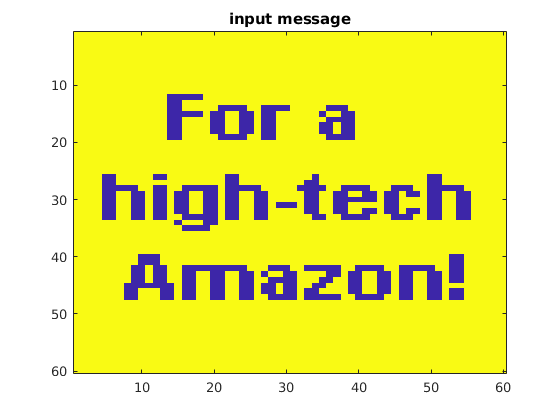

inputImage=load('/home/rodrigo/Documentos/documendos_ssd/documentos mestrado/matérias/digital_transmission/digital_transmission_git/fsk_trans/image.txt');  %load image from file
txBitstream=inputImage(:);%convert matrix to a column vector
imagesc(inputImage); title('input message');

Now we will define the constraints of the transmission, like sampling frequency, the basis functions, and the channel parameters.

f0 = 500;
f1 = 1000;
% f0 = 1650; %freq. do bit 0
% f1 = 1850;   %freq. do bit 1
%11025 to 13230
fsymbol = 550; %550;  %symbol frequency, the rate is R = 1/fsymbol(in symbols/sec or bauds)
Fs = 44.1*1e3; %sampling frequency in Hz
set_vendor_parameters(Fs,fsymbol,f1,f0,length(txBitstream));
vendor_params = get_vendor_parameters;
[preamble,preamble_fsk] = get_preamble;
% new_bit_stream = zeros(1,length(txBitstream')+vendor_params.preamble_size);
% new_bit_stream(1:vendor_params.preamble_size) = preamble;
% new_bit_stream(vendor_params.preamble_size+1:end) = txBitstream;
% txBitstream = new_bit_stream';

Modulation

s = your_transmiter(txBitstream);

    "Power of s (dBm) : "    "20"

    "Power of s (W) : "    "0.1"



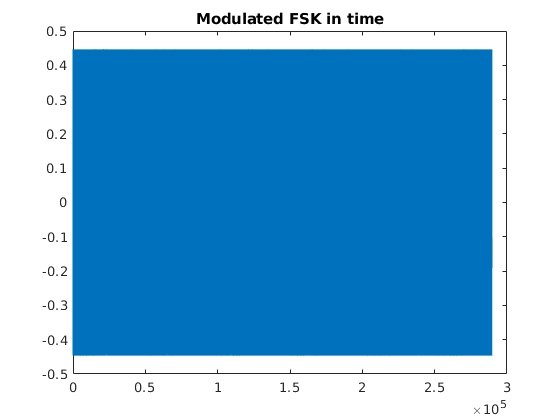

plot(real(s(:)'));
%plot(x_total_in_time);
title(['Modulated FSK in time']);

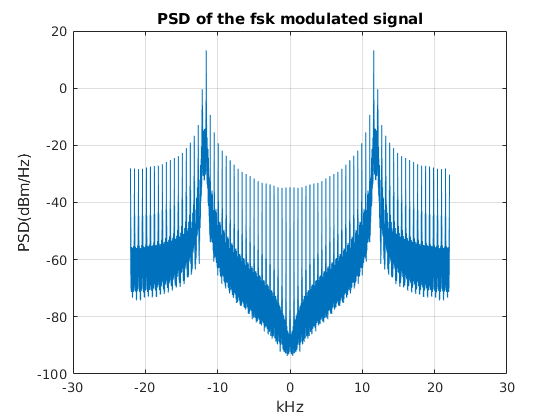

[psdIndB,f]=ak_psd(s(:)',Fs);
%[psdIndB,f]=ak_psd(x_total_in_time,Fs);
plot(f/1e3,psdIndB);
title(['PSD of the fsk modulated signal']);
xlabel('kHz') ;
ylabel('PSD(dBm/Hz)');
grid on;

Pass s through the channel

r = channel(s(:)');

    "SNR : "    "4.9953"



correction = calc_phase_correction(r,s(:)');

phase diference between r and is :36


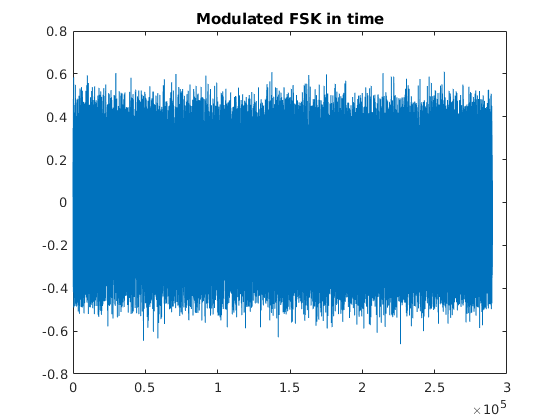

r_size = length(r);
%r = r(correction:r_size); % discart the first samples with the correction size

% size_s = size(s);
% N_symbols = size_s(2);
% r=reshape(r, vendor_params.N_samplesPerSymbol, N_symbols);
plot(real(r(:)'));
%plot(x_total_in_time);
title(['Modulated FSK in time']);

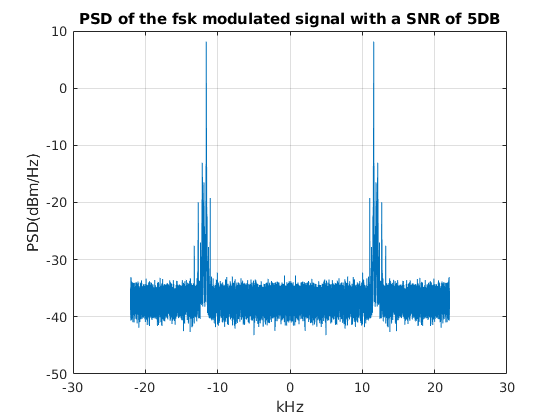

[psdIndB,f]=ak_psd(r(:)',Fs);
%[psdIndB,f]=ak_psd(x_total_in_time,Fs);
plot(f/1e3,psdIndB);
title(['PSD of the fsk modulated signal with a SNR of 5DB']);
xlabel('kHz') ;
ylabel('PSD(dBm/Hz)');
grid on;

Demodulate the FSK signal to bits

[rxBitstream,receivedCoefficients] = your_receiver(r);

phase diference between r and is :47
    0.5858

phase diference between r and is :47


Results

%%%%%%%%%%%%%%%%%%%
%Evaluation
%%%%%%%%%%%%%%%%%%%
%count number of de errors:
numErrors = sum(abs(txBitstream- rxBitstream));
BER = 100 * numErrors / length(txBitstream);
disp(['BER = ' num2str(BER) ' %']);

BER = 0 %


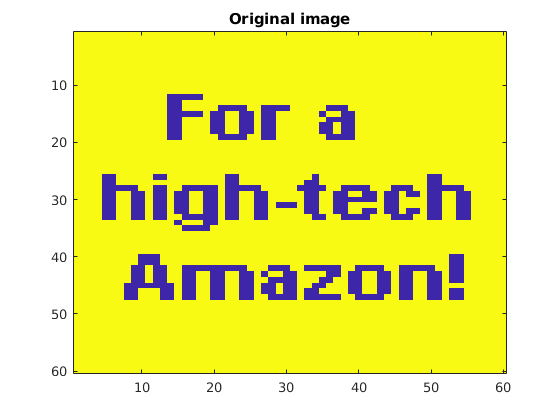

%show the images
imagesc(inputImage); title('Original image'); %show image

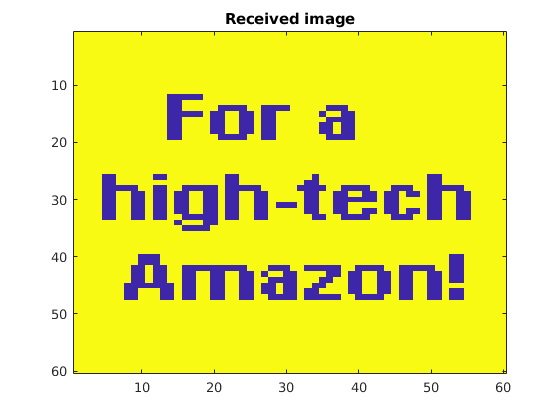

[Nrow, Ncolumns] = size(inputImage);
new_rxBitstream = rxBitstream(vendor_params.preamble_size+1:length(rxBitstream));
receivedImage=reshape(rxBitstream,Nrow, Ncolumns);
imagesc(receivedImage); title('Received image');

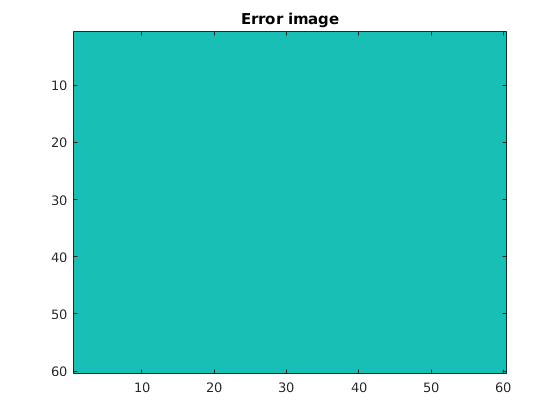

imagesc(inputImage - receivedImage); title('Error image');

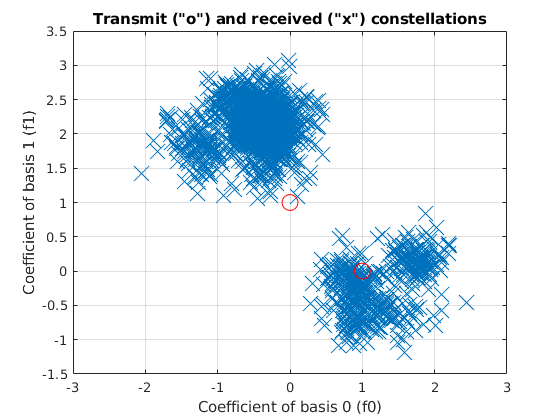

%show the constellations
% new_rx = rxBitstream_to_symbols(rxBitstream);
new_rx = receivedCoefficients;
plot(new_rx(1,:),new_rx(2,:),'x',...
    'MarkerSize',16); hold on
plot(vendor_params.X0(1),vendor_params.X0(2),'or','MarkerSize',12); 
plot(vendor_params.X1(1),vendor_params.X1(2),'or','MarkerSize',12);
title('Transmit ("o") and received ("x") constellations');
xlabel('Coefficient of basis 0 (f0)');
ylabel('Coefficient of basis 1 (f1)');
grid

% axis([-0.2 1.2 -0.2 1.2])
total_time = vendor_params.T_symbolDuration*(length(txBitstream)+vendor_params.preamble_size)

total_time = 6.5818

total_bits = length(txBitstream);
baud_rate = total_bits/total_time;
disp(["transmission rate in bauds: ", num2str(baud_rate)]);

    "transmission rate in bauds: "    "546.9613"



disp(["transmission rate in bits/sec :", num2str(baud_rate*1)]);

    "transmission rate in bits/sec :"    "546.9613"



Functions

function sn = SNR_c(x,v)
    x = abs(x);
    v = abs(v);
    P_x = 1*(sum(x.^2)) /length(x);
    P_v = 1*(sum(v.^2)) /length(v);
    sn = 10*log10(P_x/P_v);
end

function db = power_db(x)
    x = abs(x);
    P_x = 1*(sum(x.^2)) /length(x);
    db = 10*log10(P_x/1e-3);
end

function set_vendor_parameters(Fs,fsymbol,f0,f1,msg_size)
    global vendor_params
    vendor_params.title = 'Vendor parameters';
    vendor_params.carrier = 0;
    vendor_params.carrier_f = 11044;
    if vendor_params.carrier == 1
        vendor_params.f0 = f0;
        vendor_params.f1 = f1;
    else
        vendor_params.f0 = f0+vendor_params.carrier_f;
        vendor_params.f1 = f1+vendor_params.carrier_f;
    end
    
    vendor_params.Fs = Fs;
    vendor_params.fsymbol = fsymbol;
    vendor_params.T_symbolDuration = 1/fsymbol;
    T_sample = 1/Fs; %sampling period in seconds
    t = 0:T_sample:vendor_params.T_symbolDuration-T_sample; %discrete-time for one symbol
    %create the waveform for each basis function
    vendor_params.basis0 = cos(2*pi* vendor_params.f0*t);
    vendor_params.basis1 = cos(2*pi*vendor_params.f1*t);
    %normalize the basis functions by the norm to obtain unity energy
%     vendor_params.basis0 = vendor_params.basis0 / sqrt(sum(vendor_params.basis0.^2));
%     vendor_params.basis1 = vendor_params.basis1 / sqrt(sum(vendor_params.basis1.^2));
    %organize bases as columns of a matrix
    vendor_params.A=[transpose(vendor_params.basis0) transpose(vendor_params.basis1)]* sqrt (2/length(vendor_params.basis0));
    vendor_params.N_samplesPerSymbol = length(vendor_params.basis0); %number of samples per symbol, also
    %known as "oversampling" factor
    %create the symbol constellation with 2 symbols
    vendor_params.X0 = [1; 0];
    vendor_params.X1 = [0; 1];
    vendor_params.preamble_size = 20;
    vendor_params.msg_size = msg_size;
    vendor_params.basis_size = length(vendor_params.basis0);
    vendor_params.carrier_f = 11025;
    
end

function r = get_vendor_parameters
    global vendor_params
    r = vendor_params;
end

function s = your_transmiter(txBitstream)
    %%%%%%%%%%%%%%%%%%%
    %Modulate to transmit
    %%%%%%%%%%%%%%%%%%%
    vendor_params = get_vendor_parameters;
    [preamble,preamble_fsk] = get_preamble;
    new_bit_stream = zeros(1,length(txBitstream')+vendor_params.preamble_size);
    new_bit_stream(1:vendor_params.preamble_size) = preamble;
    new_bit_stream(vendor_params.preamble_size+1:end) = txBitstream;
    txBitstream = new_bit_stream';
    N_symbols = length(txBitstream); %number of symbols (or bits, because binary)
    %pre-allocate space for all message duration:
    x_total=zeros(vendor_params.N_samplesPerSymbol, N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        if txBitstream(i)==1
            X=vendor_params.X1; %transmit the symbol corresponding to bit 1
        else
            X=vendor_params.X0; %transmit the symbol corresponding to bit 0
        end
        x_total(:,i) = vendor_params.A*X; %modulate via block transform
    end
    x_total_in_time = x_total(:)';
    if vendor_params.carrier == 1
        n = [1:length(x_total_in_time)]/vendor_params.Fs;
        up_carrier = exp(-j*2*pi*vendor_params.carrier_f*n); %carrier
        x_total_in_time = times(x_total_in_time,up_carrier);
        N_symbols = vendor_params.msg_size+vendor_params.preamble_size;
        s=reshape(x_total_in_time, vendor_params.N_samplesPerSymbol, N_symbols);
    else
        s = x_total;
    end
    
    wanted_power_db = 20;
    old_px = mean(abs(x_total_in_time).^2);
    pwr_factor = sqrt(((1e-3)*10.^(wanted_power_db/10))/old_px) ;
    s = s*pwr_factor;
    
    disp(["Power of s (dBm) : ", num2str(power_db(s(:)'))]);
    disp(["Power of s (W) : ", num2str(mean(abs(s(:)').^2))]);
    
end

function [s,v] = your_receiver(r)
    %%%%%%%%%%%%%%%%%%%
    %Initialize receiver (demodulator)
    %%%%%%%%%%%%%%%%%%%
    vendor_params = get_vendor_parameters;
    if vendor_params.carrier == 1
        n = [1:length(r)]/vendor_params.Fs;
        down_carrier = exp(j*2*pi*(vendor_params.carrier_f)*n); %carrier
        r = times(r,down_carrier);
        [psdIndB,f]=ak_psd(r(:)',vendor_params.Fs);
        %[psdIndB,f]=ak_psd(x_total_in_time,Fs);
        plot(f/1e3,psdIndB);
        title(['PSD of the fsk freq downconverted and filtered']);
        xlabel('kHz') ;
        ylabel('PSD(dBm/Hz)');
        grid on;
        [B,A]=butter(10,2000/(vendor_params.Fs/2));
        dataIn = r;
        dataOut = filter(B,A,dataIn);
        r = dataOut;
        
    end
    
    [preamble,preamble_fsk] = get_preamble;
    phase_diff = calc_phase_correction(r(:)',preamble_fsk);
    received_preamble = r(:,[phase_diff+1:vendor_params.preamble_size*vendor_params.basis_size+phase_diff]);
    equalizer_factor = mean(received_preamble(:)'./preamble_fsk(:)');
    r = r/real(equalizer_factor);
    disp(real(equalizer_factor));
    starting_point = calc_phase_correction(r(:)',preamble_fsk)+vendor_params.preamble_size*vendor_params.basis_size; 
    ending_point   = vendor_params.msg_size*vendor_params.basis_size+starting_point;
    r = r(starting_point+1:ending_point);
    Ah = vendor_params.A'; %assume that A is unitary and the inverse is the Hermitian
    %%%%%%%%%%%%%%%%%%%
    %Demodulate the received signal
    %%%%%%%%%%%%%%%%%%%
    %Note that we assume the basis functions were created in the receiver
    %with perfect synchronism to the transmitter. Hence, it is an ideal
    %"synchronous" reception.
    
    size_r = size(r);
    N_symbols = vendor_params.msg_size;
    outputBits = zeros(N_symbols,1); %pre-allocate space
    receivedCoefficients = zeros(2,N_symbols); %pre-allocate space
    %reorganize y_total as a matrix for simplicity
    r=reshape(r, vendor_params.N_samplesPerSymbol, N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        x=r(:,i);
        %demodulate via block transform ("correlative decoding")
        X = Ah * x; %calculate the inner product with each basis function
        receivedCoefficients(:,i) = X;
        %find the constellation point nearest to the coefficients X:
        distanceToSymbol0 = sqrt(sum( (X-vendor_params.X0).^2 ));
        distanceToSymbol1 = sqrt(sum( (X-vendor_params.X1).^2 ));
        if distanceToSymbol0 < distanceToSymbol1
            outputBits(i) = 0; %symbol 0 is the closest one
        else
            outputBits(i) = 1; %symbol 1 is the closest one
        end
    end
    
    s = outputBits;
    v = receivedCoefficients;
end

function r = channel(s)
    [B,A]=cheby1(8,12,[0.5 0.6],'bandpass');  
    %this channel has a passband from 0.5pi to 0.6pi, which
    %corresponds to 0.5(Fs/2) to 0.6(Fs/2). For Fs=44.1 kHz,
    %this gives a band from 11025 to 13230, BW=2205 Hz
    
    h=impz(B,A,400); %approximate h[n] with 400 samples
    z=conv(s(:)',h); %note that z is longer than x
    randn('seed',319); % set random seed
    P_x = mean(abs(z).^2);
    SNRdB = 5; %desired signal to noise ratio in dB
    SNR=10^(0.1*SNRdB); %SNR in linear scale
    noisePower = P_x/SNR; %noise power
    wgn = sqrt(noisePower)*randn(size(z)); %Gaussian noise
    r = z+wgn;% Add the gaussian white noise
    disp(["SNR : ", num2str(SNR_c(z,wgn))]);
end

function sv = rxBitstream_to_symbols(r)
    size_r = size(r);
    N_symbols = size_r(1);
    r = r';
    sv = zeros(2,N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        bit_i =r(i);
        if bit_i == 1
            bit_j = 0; %symbol 0 is the closest one
        else
            bit_j = 1; %symbol 1 is the closest one
        end
        sv(:,i) = [bit_i; bit_j];
    end
end

function c_o = calc_phase_correction(z,s)
    [c,lags] = xcorr(z,s(:)');
    [c,lags] = xcorr(z,s(:)');
    [M,max_index] = max(c);
    phase_diff = lags(max_index);
    disp(['phase diference between r and is :',num2str(phase_diff)]);
    c_o = abs(phase_diff);

end

function s = bits_to_fsk(bits)
    vendor_params = get_vendor_parameters;
    N_symbols = length(bits); %number of symbols (or bits, because binary)
    %pre-allocate space for all message duration:
    x_total=zeros(vendor_params.N_samplesPerSymbol, N_symbols);
    for i=1:N_symbols  %i is the i-th symbol
        if bits(i)==1
            X=vendor_params.X1; %transmit the symbol corresponding to bit 1
        else
            X=vendor_params.X0; %transmit the symbol corresponding to bit 0
        end
        x_total(:,i) = vendor_params.A*X; %modulate via block transform
    end
    s = x_total;
end

function [p,fsk] = get_preamble
    vendor_params = get_vendor_parameters;
    preamble = zeros(1,vendor_params.preamble_size);
    preamble(1:2:end) = 1;
    preamble_fsk = bits_to_fsk(preamble);
    p = preamble;
    fsk = preamble_fsk;
end